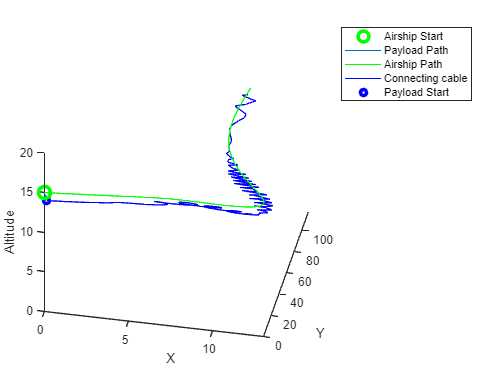

clc
clear
clf
%load("nonlinearModelData.mat")
%load("Ploting/testenonLinearDataV2.mat")
load("Ploting/LinearData.mat")
%load("Ploting/LinearData_Wind.mat")


l = 1; %if changed in model change here also

Xp = y(:,1) + l .* sin(y(:,4)) .*cos(y(:,5));
Yp = y(:,2) + l .* sin(y(:,4)) .*sin(y(:,5));
Zp = y(:,3) - l.*cos(y(:,4));

Xup = 10;
Xlow =0;
Yup = 30;
Ylow =0;
Zup = 20;
Zlow =0;
hold on
    Xa_i = y(1,1);
    Ya_i = y(1,2);
    Za_i = y(1,3);
    
    Xp_i = Xp(1);
    Yp_i = Yp(1);
    Zp_i = Zp(1);
    

    connect = [Xa_i Ya_i Za_i;Xp_i Yp_i Zp_i];
     
    plot3(Xa_i,Ya_i,Za_i, 'go','LineWidth',3,'MarkerSize',10)
     xlim([Xlow Xup]);
     ylim([Ylow Yup]);
     zlim([Zlow Zup]);
     xlabel('X')
    ylabel('Y')
    zlabel('Altitude')
     
    
    line(connect(:,1),connect(:,2),connect(:,3))
    plot3(y(:,1),y(:,2),y(:,3),'g')
    plot3(Xp,Yp,Zp,'b')
    plot3(Xp_i,Yp_i,Zp_i, 'bo','LineWidth',3,'MarkerSize',5)
    view([-2.6 17.6]);
    legend('Airship Start','Payload Path','Airship Path','Connecting cable','Payload Start')
 hold off

 %exportgraphics(gcf,'LinearSim_Alpha5Beta5_Moving.pdf','Resolution',300)